## L4 - TC2

Tsubida = 20.298 * 10^(-3);
T = Tsubida/10

T = 0.0020

Gc = tf([7898 54390 91200], [1 100 2500])

Gc =
 
  7898 s^2 + 54390 s + 91200
  --------------------------
      s^2 + 100 s + 2500
 
Continuous-time transfer function.
Model Properties


Gz = c2d(Gc, T, 'zoh')

Gz =
 
  7898 z^2 - 1.566e04 z + 7760
  ----------------------------
     z^2 - 1.807 z + 0.8163
 
Sample time: 0.0020298 seconds
Discrete-time transfer function.
Model Properties


% Discretizar la planta
Gp = tf(1.16, [1 4.4 5.6 16])

Gp =
 
             1.16
  --------------------------
  s^3 + 4.4 s^2 + 5.6 s + 16
 
Continuous-time transfer function.
Model Properties


Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
  1.613e-09 z^2 + 6.439e-09 z + 1.606e-09
  ---------------------------------------
    z^3 - 2.991 z^2 + 2.982 z - 0.9911
 
Sample time: 0.0020298 seconds
Discrete-time transfer function.
Model Properties


Gsz = feedback(Gz*Gpz, 1, -1)

Gsz =
 
  1.274e-05 z^4 + 2.559e-05 z^3 - 7.561e-05 z^2 + 2.482e-05 z + 1.246e-05
  -----------------------------------------------------------------------
         z^5 - 4.798 z^4 + 9.203 z^3 - 8.822 z^2 + 4.225 z - 0.809
 
Sample time: 0.0020298 seconds
Discrete-time transfer function.
Model Properties


kf = 100;
qdato = [];
r_1 = 0, r_2 = 0, r_3 = 0, r_4 = 0, r_5 = 0;

r_1 = 0

r_2 = 0

r_3 = 0

r_4 = 0

q_1 = 0, q_2 = 0, q_3 = 0, q_4 = 0, q_5 = 0;

q_1 = 0

q_2 = 0

q_3 = 0

q_4 = 0

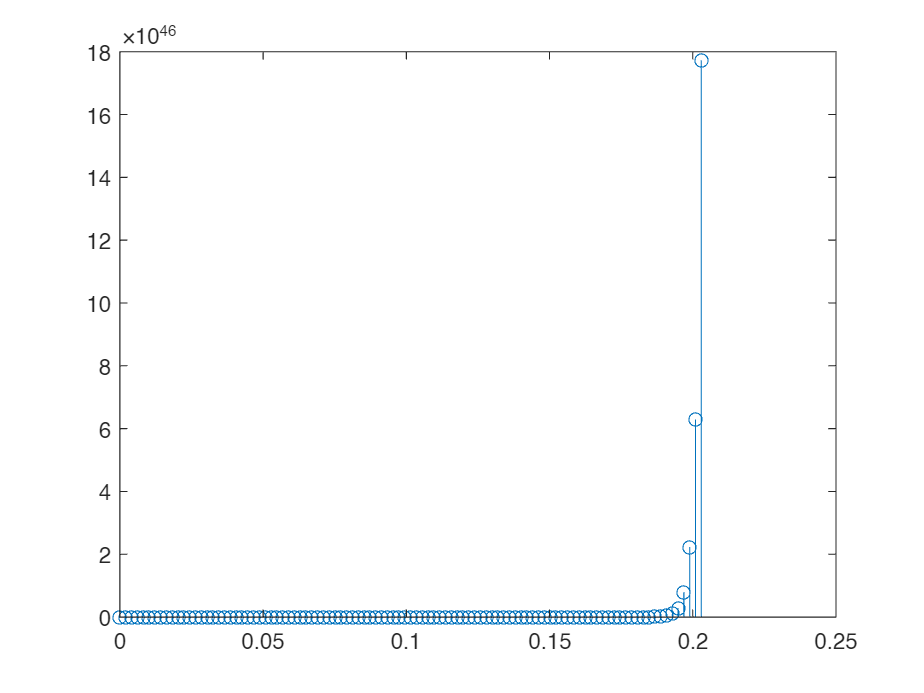

r = 0.1;


for k=0:kf
    q = 7898*r - 3.928e04*r_1 + 7.815e04*r_2 - 7.774e04*r_3 + 3.866e04*r_4 - 7691*r_5 + 4.798*q_1 - 9.203*q_2 + 8.822*q_3 + 4.225*q_4 - 0.809*q_5;
    qdato = [qdato q];
    q_5 = q_4;
    q_4 = q_3;
    q_3 = q_2;
    q_2 = q_1;
    q_1 = q;
    r_5 = r_4;
    r_4 = r_3;
    r_3 = r_2;
    r_2 = r_1;
    r_1 = r;
end;

stem((0:kf)*T, qdato)